clc;
clear all;
% Read the .wav file
[inputSignal, Fs] = audioread('Goutami.wav');
T = 1 / Fs;             % Sampling period
t = 0:T:1;              % Time vector

% Define filter specifications
cutoffFrequency = 3000;  % Set your desired cutoff frequency in Hz
[h,t] = myOrder();  % Choose the filter order (adjust as needed)

Kp = -3

Ks = -20

Fp = 3000

Fs = 3200

Omega_p = 1.8850e+04

Omega_s = 2.0106e+04

Sampling_Time = 4.1667e-05

Wp = 0.7854

Ws = 0.8378

Omega_p_new = 0.8284

Omega_s_new = 0.8905

N = 32

theta = 7.2832

s = 0.5403 + 0.8415i

theta =     7.2832    8.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i


theta =     7.2832    8.2832    9.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i


theta =     7.2832    8.2832    9.2832   10.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832   31.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i   0.9912 - 0.1324i


theta =     7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832   31.2832   32.2832


s =    0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i   0.9912 - 0.1324i   0.6469 + 0.7626i


theta = 1×27
    7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832   31.2832   32.2832   33.2832


s = 1×27
   0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i   0.9912 - 0.1324i   0.6469 + 0.7626i  -0.2921 + 0.9564i


theta = 1×28
    7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832   31.2832   32.2832   33.2832   34.2832


s = 1×28
   0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i   0.9912 - 0.1324i   0.6469 + 0.7626i  -0.2921 + 0.9564i  -0.9626 + 0.2709i


theta = 1×29
    7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832   31.2832   32.2832   33.2832   34.2832   35.2832


s = 1×29
   0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i   0.9912 - 0.1324i   0.6469 + 0.7626i  -0.2921 + 0.9564i  -0.9626 + 0.2709i  -0.7481 - 0.6636i


theta = 1×30
    7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832   31.2832   32.2832   33.2832   34.2832   35.2832   36.2832


s = 1×30
   0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i   0.9912 - 0.1324i   0.6469 + 0.7626i  -0.2921 + 0.9564i  -0.9626 + 0.2709i  -0.7481 - 0.6636i   0.1543 - 0.9880i


theta = 1×31
    7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832   31.2832   32.2832   33.2832   34.2832   35.2832   36.2832


s = 1×31
   0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i   0.9912 - 0.1324i   0.6469 + 0.7626i  -0.2921 + 0.9564i  -0.9626 + 0.2709i  -0.7481 - 0.6636i   0.1543 - 0.9880i


theta = 1×32
    7.2832    8.2832    9.2832   10.2832   11.2832   12.2832   13.2832   14.2832   15.2832   16.2832   17.2832   18.2832   19.2832   20.2832   21.2832   22.2832   23.2832   24.2832   25.2832   26.2832   27.2832   28.2832   29.2832   30.2832   31.2832   32.2832   33.2832   34.2832   35.2832   36.2832


s = 1×32
   0.5403 + 0.8415i  -0.4161 + 0.9093i  -0.9900 + 0.1411i  -0.6536 - 0.7568i   0.2837 - 0.9589i   0.9602 - 0.2794i   0.7539 + 0.6570i  -0.1455 + 0.9894i  -0.9111 + 0.4121i  -0.8391 - 0.5440i   0.0044 - 1.0000i   0.8439 - 0.5366i   0.9074 + 0.4202i   0.1367 + 0.9906i  -0.7597 + 0.6503i  -0.9577 - 0.2879i  -0.2752 - 0.9614i   0.6603 - 0.7510i   0.9887 + 0.1499i   0.4081 + 0.9129i  -0.5477 + 0.8367i  -1.0000 - 0.0089i  -0.5328 - 0.8462i   0.4242 - 0.9056i   0.9912 - 0.1324i   0.6469 + 0.7626i  -0.2921 + 0.9564i  -0.9626 + 0.2709i  -0.7481 - 0.6636i   0.1543 - 0.9880i


gain = 1

poles = 1×15
   -0.4161   -0.9900   -0.6536   -0.1455   -0.9111   -0.8391   -0.7597   -0.9577   -0.2752   -0.5477   -1.0000   -0.5328   -0.2921   -0.9626   -0.7481


Transfer_function =
 
                                                                                1
  -------------------------------------------------------------------------------------------------------------------------------------------------------------
  (s+0.4161) (s+0.5328) (s+0.5477) (s+0.6536) (s+0.7481) (s+0.7597) (s+0.8391) (s+0.9111) (s+0.9577) (s+0.9626) (s+0.99) (s+1) (s+0.2921) (s+0.2752) (s+0.1455)
 
Continuous-time zero/pole/gain model.


cutoff_frequency = 0.8285

SYSD =
 
  -9.9056e-18 (z-1)^13
  --------------------
        (z-1)^15
 
Sample time: 4.1667e-05 seconds
Discrete-time zero/pole/gain model.
Model Properties


numerator = 1×16
1.0e-13 *

         0         0   -0.0001    0.0013   -0.0077    0.0283   -0.0708    0.1275   -0.1700    0.1699   -0.1275    0.0708   -0.0283    0.0077   -0.0013    0.0001


denominator = 1×16
1.0e+03 *

    0.0010   -0.0150    0.1050   -0.4550    1.3648   -3.0026    5.0042   -6.4337    6.4336   -5.0037    3.0022   -1.3646    0.4548   -0.1050    0.0150   -0.0010


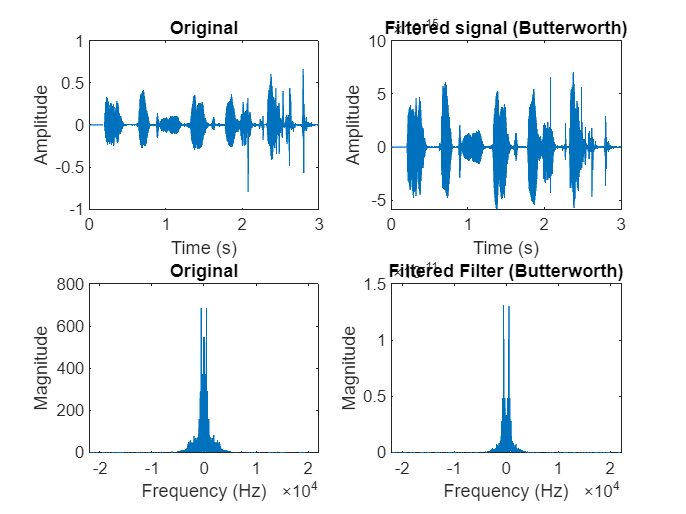

%y_n=conv(h_n,inputSignal);
% Design Butterworth filter without using inbuilt function
% Apply the filter to the signal using a direct form II transposed structure


filteredSignal = conv(inputSignal,h);

figure;
subplot(2,2,1);
t = (0:length(inputSignal)-1) / Fs;
plot(t, inputSignal);
title('Original');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(filteredSignal)-1) / Fs; % Time vector

subplot(2,2,2);
plot(t, filteredSignal);
title('Filtered signal (Butterworth)');
xlabel('Time (s)');
ylabel('Amplitude');

n = length(inputSignal);  % Set n based on the length of the signal
y = fft(inputSignal, n);
m = abs(y);
f = (0:length(y)-1) * Fs / length(y);
Y = fftshift(m);
fshift = (-n/2:n/2-1) * (Fs/n);

% Filtered
nf = length(filteredSignal);  % Set n based on the length of the signal
yf = fft(filteredSignal, nf);
mf = abs(yf);
ff = (0:length(yf)-1) *Fs / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (Fs/nf);

subplot(2,2,3);
plot(fshift, Y);
title('Original');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered Filter (Butterworth)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


%ORDER


function [h,t] = myOrder()
Kp=-3
Ks=-20
Fp=3000
Fs=3200
Omega_p=2*pi*Fp
Omega_s=2*pi*Fs
Sampling_Time=(1/(24*10^3))
%Digital Low pass filter specifications
Wp=Omega_p*Sampling_Time
Ws=Omega_s*Sampling_Time

%%Prewarp the band edge frequencies using T=1 sec,
T=1;
Omega_p_new=(2/T)*tan(Wp/2)
Omega_s_new=(2/T)*tan(Ws/2)
%Order of Butterworth low pass filter
N=ceil((log10((10^(-0.1 * Kp) - 1) / (10^(-0.1 * Ks) - 1))) / (2 * log10(Omega_p_new / Omega_s_new)))

%%Poles of the normalized lowpass Butterworth filter
for k=1:N
    theta(k)=(k-1*pi/2)+(pi*2)+(pi/2)
   s(k) = cos(theta(k)) + 1i*sin(theta(k))

end
gain=1
zeros = [];
poles = [s];
poles= real(poles(real(poles) < 0))

Transfer_function = zpk(zeros,poles,gain)     %h(s)
%Cutoff frequency
cutoff_frequency=Omega_p_new / ((10^(-0.1 * Kp)) - 1)^(1/(2 * N))
%Digital filter transfer function
 SYSD = c2d(Transfer_function,Sampling_Time,'impulse')   %h(z)

% Assuming t_rf_d is a discrete-time transfer function
syms h t

% Extract coefficients directly from the transfer function
[numerator, denominator] = tfdata(SYSD, 'v')

% Create the Z-domain transfer function
H_z = tf2zpk(numerator, denominator);

% Perform the inverse Z-transform
[h,t] = impz(numerator,denominator);

end